# Assignement C2* correction by S. Coniglio & J. Morlier

## May 2018

%Initialization of Variables
clear all; close all;
format long
Eb = 3.2e10; % Beam [Pa]
Ea = 2.0e11; % Bar [Pa]
L =3; % Beam [m]
h =0.3; % Beam [m]
Ap = h^2; % Beam [m*m]
I = h^4/12; %Beam [m^4]
Ab = .0025; % Bar [m*m]
Lb = L/2; % Bar [m]
q0 = 10e3; % N/m


% Stifness matrix Beam
Kf = Eb*I/L^3*[12	6*L	-12	6*L;
6*L 4*L^2 -6*L 2*L^2 ;-12 -6*L	12 -6*L;
6*L 2*L^2 -6*L 4*L^2];



%PART1
F=[0 0 -75000 0]';

%Reduced system to solve in the global/local axis
K1=Kf(3:4,3:4); %MN/m
F1=F(3:4);
U1=K1\F1;
U1(1)%m;

ans =   -0.031250000000000


U1(2)%rad;				

ans =   -0.015625000000000


*v *= −*3.125 cm*

θ = −*1.563 10*−*2 **rad *

%Check the reaction forces
Ue=[0 0 U1']'

Ue =                    0
                   0
  -0.031250000000000
  -0.015625000000000


Fe=Kf*Ue					

Fe =    1.0e+05 *

   0.750000000000001
   2.250000000000002
  -0.750000000000001
   0.000000000000000


 *Rz = 75 KN and* *My = 225 KNm (75KN *× *3m) *



%PART2
warning q0 is in KN/m

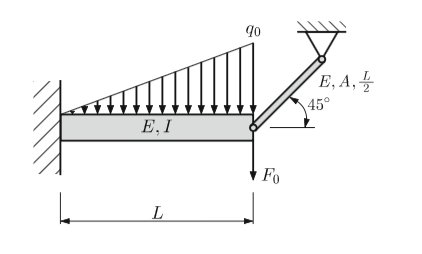

Part of the job was to find equivalence forces for the distributed load ! see class exercice and script on github. You can find the results in the next figure.

Then discretize the structure use only 2 elements: 1 beam and 1 bar.

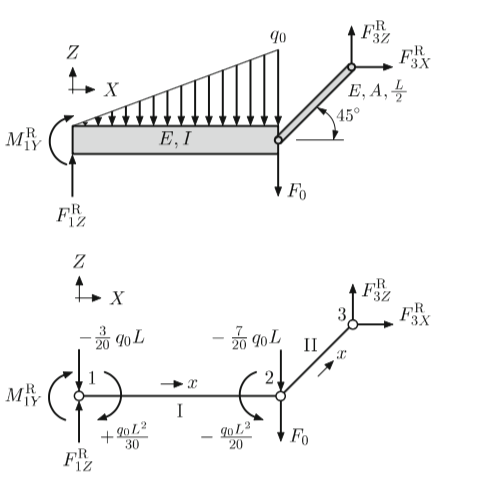

  
% Stiffness matrix beam
Kf = Eb*I/L^3*[12	6*L	-12	6*L;
6*L 4*L^2 -6*L 2*L^2 ;-12 -6*L	12 -6*L;
6*L 2*L^2 -6*L 4*L^2];

% add axial behaviour
Ka=Eb*Ap/L*[1 -1; -1 1];
% axial bending behaviour
Kp([ 2 3 5 6 ] , [2 3 5 6 ]) = Kf; Kp([1 4], [1 4 ]) = Ka;
% augmnented bar 
Kb = zeros(6); Kb([1 4 ], [1 4]) =Ea*Ab/Lb*[ 1 -1; -1 1]

Kb =    1.0e+08 *

   3.333333333333333                   0                   0  -3.333333333333333                   0                   0
                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0                   0
  -3.333333333333333                   0                   0   3.333333333333333                   0                   0
                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0                   0



%Rotation (45)
c = sqrt(1/2); s = sqrt(1/2); r=[c s 0;
    -s c 0;
0 0 1];

R = kron(eye(2),r); %Simpliciation
Kb=(R)'*Kb*R;

% Assembly
K = zeros(9);
K(1:6 , 1:6 ) = K(1:6 , 1:6 )+Kp

K =    1.0e+08 *

   9.600000000000000                   0                   0  -9.600000000000000                   0                   0                   0                   0                   0
                   0   0.096000000000000   0.144000000000000                   0  -0.096000000000000   0.144000000000000                   0                   0                   0
                   0   0.144000000000000   0.288000000000000                   0  -0.144000000000000   0.144000000000000                   0                   0                   0
  -9.600000000000000                   0                   0   9.600000000000000                   0                   0                   0                   0                   0
                   0  -0.096000000000000  -0.144000000000000                   0   0.096000000000000  -0.144000000000000                   0                   0                   0
                   0   0.144000000000000   0.144000000000000                 

K(4:9 , 4:9 ) = K(4:9 , 4:9 )+Kb

K =    1.0e+09 *

   0.960000000000000                   0                   0  -0.960000000000000                   0                   0                   0                   0                   0
                   0   0.009600000000000   0.014400000000000                   0  -0.009600000000000   0.014400000000000                   0                   0                   0
                   0   0.014400000000000   0.028800000000000                   0  -0.014400000000000   0.014400000000000                   0                   0                   0
  -0.960000000000000                   0                   0   1.126666666666667   0.166666666666667                   0  -0.166666666666667  -0.166666666666667                   0
                   0  -0.009600000000000  -0.014400000000000   0.166666666666667   0.176266666666667  -0.014400000000000  -0.166666666666667  -0.166666666666667                   0
                   0   0.014400000000000   0.014400000000000                 


% BCs

	The obvious support conditions are at node 1 and 3, i.e. *u*1*Z *= 0, φ1*Y *= 0 and *u*3*X *= *u*3*Z *= 0. However, it is also important to consider that the beam cannot have anyelongationinthe*X*-directionatnode2:*u*2*X *=0. 

i=[1,2,3,4,7,8,9];
Kreduced=K;
Kreduced(:,i) = []; 
Kreduced(i,:) = []

Kreduced =    1.0e+08 *

   1.762666666666667  -0.144000000000000
  -0.144000000000000   0.288000000000000


Handwritten gives K_theory

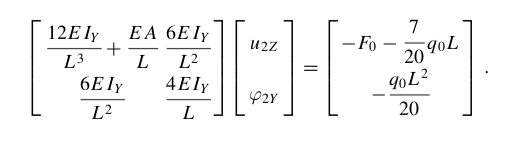

K_theory=[(12*Eb*I/(L^3))+(Ea*Ab)/(L) -6*Eb*I/(L^2); -6*Eb*I/(L^2) 4*Eb*I/(L)]

K_theory =    1.0e+08 *

   1.762666666666667  -0.144000000000000
  -0.144000000000000   0.288000000000000


f = [ 0;0;0;0 ;-75e3 + -7*q0*L/20 ; -1*q0*L*L ;0 ;0 ;0];%Assembly of ecternal forces
freduced=[-75e3 + -7*q0*L/20 ; -1*q0*L*L]

freduced =       -85500
      -90000


Ureduced = Kreduced\freduced%solution

Ureduced =   -0.000771884858044
  -0.003510942429022


*Stiff ! isn't it?*

U_theory = K_theory\freduced  %solution

U_theory =   -0.000771884858044
  -0.003510942429022


Internal forces:

Here we compute the internal force in the global coordinate system

Fbeam = Kp * [0 0 0 0 Ureduced' ]' %[Fx1 Fy1 Mz1 Fx2 Fy2 Mz2]

Fbeam =    1.0e+04 *

                   0
  -4.314747634069400
  -3.944242902208202
                   0
   4.314747634069400
  -8.999999999999998


Beam in compression -43kN

Fbar = Kb * [ 0 Ureduced' 0 0 0]' %[Fx2 Fy2 Mz2 Fx3 Fy3 Mz3]

Fbar =    1.0e+05 *

  -1.286474763406940
  -1.286474763406940
                   0
   1.286474763406940
   1.286474763406940
                   0


To know the bar stress state one can compute the local displacement using the rotation matrix that traduces the bar global displacement into the local one.

ub_local=R*[ 0 Ureduced' 0 0 0]' %[ul1 vl1 thetal1 ul2 vl2 thetal12] where l1==2 and l2==3

ub_local =   -0.000545805017418
  -0.000545805017418
  -0.003510942429022
                   0
                   0
                   0


the axial displacements necessary for the bar internal stress post processig are the only components 1 and 4:

ub_axial=ub_local([1,4]) %[ul1 ul2]

ub_axial =    1.0e-03 *

  -0.545805017418244
                   0


the bar axial deformation $\varepsilon_{xx} =Bu$  can be computed using the strain displacement matrix (introduced during lectures):

B_bar=[-1/Lb 1/Lb]; % strain displacement matrix of the linear bar element
eps_bar=B_bar*ub_axial

eps_bar =      3.638700116121627e-04


That means that the bar is in traction, for the stress $\sigma_{xx} =E\varepsilon_{xx}$ (the stress strain matrix D here is a scalar):

sigma_bar=Eb*eps_bar %Pa

sigma_bar =      1.164384037158921e+07


finally the normal load is $N=A\sigma_{xx}$

InternalFbar= Ab*sigma_bar %N

InternalFbar =      2.910960092897302e+04


The Bar is in traction  state 29KN are applied to both extremities in opposite directions along the bar axis direction. 

%partionned
%   Special case: ALL imposed displacements are zero 
% (Ub = 0)
freedofs=[5:6];
constraineddofs=[1:4 7:9];
Kaa=K(freedofs,freedofs)

Kaa =    1.0e+08 *

   1.762666666666667  -0.144000000000000
  -0.144000000000000   0.288000000000000


Kba=K(constraineddofs,freedofs)

Kba =    1.0e+08 *

                   0                   0
  -0.096000000000000   0.144000000000000
  -0.144000000000000   0.144000000000000
   1.666666666666667                   0
  -1.666666666666667                   0
  -1.666666666666667                   0
                   0                   0


fa=f(freedofs)

fa =       -85500
      -90000


Ua=inv(Kaa)*fa

Ua =   -0.000771884858044
  -0.003510942429022


reactions=Kba*Ua

reactions =    1.0e+05 *

                   0
  -0.431474763406940
  -0.394424290220820
  -1.286474763406940
   1.286474763406940
   1.286474763406940
                   0


reactions_glob = [reactions(1:4); 0 ;0;reactions(5:7)]

reactions_glob =    1.0e+05 *

                   0
  -0.431474763406940
  -0.394424290220820
  -1.286474763406940
                   0
                   0
   1.286474763406940
   1.286474763406940
                   0


Need to check the balance of forces ...

balance_x=sum(reactions_glob([1,4,7])+f([1,4,7]))

balance_x =      0


balance_z=sum(reactions_glob([2,5,8])+f([2,5,8]))

balance_z =      0


balance_my=sum(reactions_glob([3,6])+f([3,6]))-(reactions_glob(2)+f(2))*L % chosing node 2 as pole

balance_my =      0
